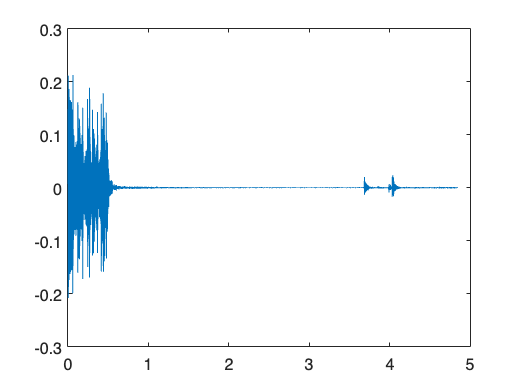

load('short_modem_rx.mat')
start_idx = find_start_of_signal(y_r, x_sync);
y_t = y_r(start_idx+length(x_sync):end);
t = 0:(1/Fs):(length(y_t)-1)/Fs;
plot(t,y_t)

soundsc(y_t,Fs)

W = f_c;
c = cos(2*pi*f_c*t);
C = fft(c);

Y_t = fft(y_t);
y_c = c .* y_t';
%w = linspace(-Fs*pi,Fs*pi-2*pi*Fs/length(Y_c),length(Y_c));
% M = Y_c(abs(w) < f_c/Fs);
% 
%hel w_crop = w(abs(w) < f_c/Fs);
% m = ifft(M);

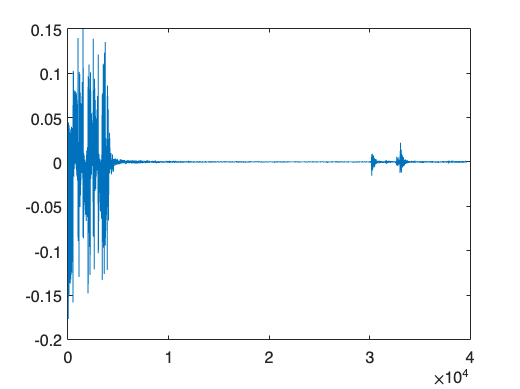

plot(y_c)

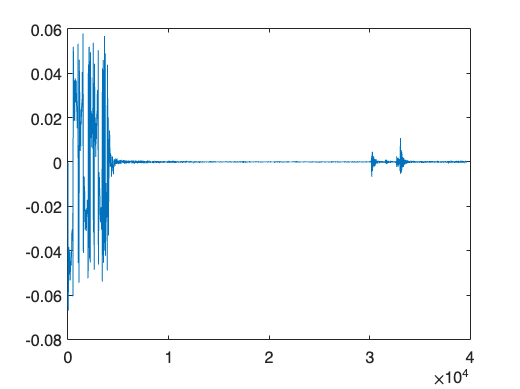

m = lowpass(y_c, f_c/Fs);
plot(m)

soundsc(m, Fs)

m_down = downsample(m, 100)

m_down =    -0.0003   -0.0468   -0.0462   -0.0406   -0.0318   -0.0511    0.0275    0.0318    0.0306    0.0211    0.0470   -0.0536    0.0141    0.0181    0.0282    0.0533   -0.0110   -0.0227   -0.0257   -0.0203   -0.0492    0.0489   -0.0408    0.0178    0.0165    0.0515   -0.0443    0.0165    0.0129    0.0225    0.0492   -0.0117   -0.0225   -0.0245   -0.0467    0.0458   -0.0336    0.0483   -0.0192   -0.0427    0.0202    0.0030    0.0009   -0.0013    0.0008   -0.0047    0.0005    0.0002   -0.0006    0.0011


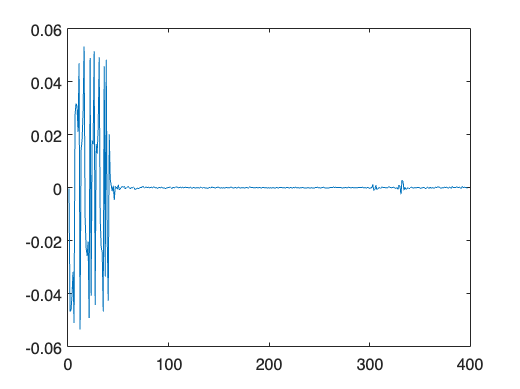

plot(m_down)

%soundsc(m_down, Fs)

m_scaled = (m_down>0)

m_scaled = 1×397 logical array
   0   0   0   0   0   0   1   1   1   1   1   0   1   1   1   1   0   0   0   0   0   1   0   1   1   1   0   1   1   1   1   0   0   0   0   1   0   1   0   0   1   1   1   0   1   0   1   1   0   1


BitsToString(m_scaled(1:64))

ans = 'TVEVz×æ'

soundsc(y_c, Fs)

soundsc(y_t, Fs)